# Multi-Objective Optimal Control of a Mobile Robot with CasADi 

## Initialization

close all
clearvars
nNodes        = 60; % Number of shooting nodes 
nParetoPoints = 20; % Number of Pareto optimal solutions
nSteps        = 0;  % Number of intermediate multiple shooting steps
T_max         = 20; % Max time to reach the final state

## Setting up the problem

Generate an opti-object that stores all information about the optimization problem to be solved.

opt = casadi.Opti();
p_opts = struct;                   % Empty struct when Casadi plugin options remain unchanged
s_opt = struct('print_level', 0);  % Stop printing all information
opt.solver('ipopt', p_opts, s_opt) % Set solver, in our case IPOPT

x_f = [7, 5, 0, pi/2, 0]';                     % Final state to reach
T   = opt.variable(1);                              % Time to reach the goal as a decision variable and cost           
x0  = [0 0 0 -135/180*pi 0]';                     % Initial condition
x   = [x0, opt.variable( 5, nNodes-2 ), x_f];     % The states are the initial state + all predicted states  
u   = opt.variable( 2, (nNodes-1) * (nSteps+1) ); % Input for each state transition
dt  = T / ((nNodes-1) * (nSteps+1));              % Step size dt for the RK4 integrator

## Setting the equality constraints to respect the dynamics

Call the Runge-Kutta 4 integrator to connect following states with equality constraints

for iStep = 1:(nNodes-1)
    initial_step = (nSteps+1) * (iStep-1)+1;
    opt.subject_to( ms_step(x(:,iStep), u(:, initial_step:(initial_step + nSteps)), dt) == x(:,iStep+1) )
end

## Box constraints

opt.subject_to( -45/180*pi <= x(5,:) <= 45/180*pi ) % box constraints on the steering angle
opt.subject_to( -20/180*pi <= u(2,:) <= 20/180*pi ) % box constraint turning velocity
opt.subject_to( -0.2 <= x(3,:) );                   % lower bound on velocity
opt.subject_to( x(1,:) <= 7.1 );                    % upper bound on x
opt.subject_to( -10 <= u(1,:) <= 5 )                % box constraint on the acceleration
opt.subject_to( 1 <= T <= T_max )                   % reach the goal in at most T_max seconds

## Add approximation for energy costs

cost_u = 0.5*u(1,:)*u(1,:)'*dt; % Approximation of the energy costs

## Find Extreme points, utopia point and nadir point

opt.minimize(T)
solT = opt.solve();

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)        0 (       0)        89
       nlp_g  |  24.00ms (269.66us)  23.65ms (265.78us)        89
  nlp_grad_f  |        0 (       0)        0 (       0)        22
  nlp_hess_l  | 520.00ms (  6.42ms) 520.41ms (  6.42ms)        81
   nlp_jac_g  | 168.00ms (  1.98ms) 167.71ms (  1.97ms)        85
       total  | 962.00ms (962.00ms) 961.93ms (961.93ms)         1


opt.minimize(cost_u)
solU = opt.solve();

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)        0 (       0)       110
       nlp_g  |  27.00ms (245.45us)  26.98ms (245.29us)       110
  nlp_grad_f  |        0 (       0)        0 (       0)        31
  nlp_hess_l  | 481.00ms (  5.40ms) 480.76ms (  5.40ms)        89
   nlp_jac_g  | 169.00ms (  1.82ms) 169.87ms (  1.83ms)        93
       total  | 929.00ms (929.00ms) 929.06ms (929.06ms)         1



% Calculate Extreme points, Utopia point and Nadir point
EP = [solT.value([T, cost_u]); solU.value([T, cost_u])];
up = min(EP, [], 1);
np = max(EP, [], 1);

## NBI

Set up Pascoletti-Serafini and call get_starting_points that interpolates between the Extreme Points.

np_sym and up_sym are parameters to be replaced by either the Nadir point and Utopia point (Normalization to [0, 1]) or ones and zeros respectively for no normalization whatsoever.

By setting d - the search direction - and s - the starting point - to parameters, their values can later be set whenever needed. This also allows for CasADi to calculate derivatives with respect to these parameters, enabeling some nice features (not part of this script or this lecture).

l = opt.variable(1);
d = opt.parameter(1,2);
s = opt.parameter(1,2);
upsym = opt.parameter(1,2);
npsym = opt.parameter(1,2);
opt.subject_to(s+l*d >= ([T, cost_u]-upsym)./(npsym-upsym))
opt.minimize(-l);
opt.set_value(d, -null(EP(2,:)-EP(1,:))')
opt.set_value(upsym, [0, 0]);
opt.set_value(npsym, [1, 1])

s_pts = get_starting_points(EP, nParetoPoints);

sol(1) = solT;
J = sol(1).value([T, cost_u]);
for iSol = 2:(nParetoPoints-1)
    opt.set_value(s, s_pts(iSol,:))

    % Under the assumption, that similar Pareto parameters produce similar
    % solutions, a parameterized problem can be initialized with a
    % solution of a problem with similar parameters. Since two starting
    % points following each other are close we can use the last solution
    % calculated.
    opt.set_initial(u,  sol(iSol-1).value(u))
    opt.set_initial(x,  sol(iSol-1).value(x))
    opt.set_initial(T,  sol(iSol-1).value(T))
    opt.set_initial(dt, sol(iSol-1).value(dt))

    sol(iSol) = opt.solve();
    J(iSol,:) = sol(iSol).value([T, cost_u]);
end

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)        0 (       0)        31
       nlp_g  |   7.00ms (225.81us)   6.99ms (225.58us)        31
    nlp_grad  |        0 (       0)        0 (       0)         1
  nlp_grad_f  |        0 (       0)        0 (       0)        26
  nlp_hess_l  | 158.00ms (  6.58ms) 158.05ms (  6.59ms)        24
   nlp_jac_g  |  63.00ms (  2.42ms)  63.08ms (  2.43ms)        26
       total  | 295.00ms (295.00ms) 295.00ms (295.00ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)        0 (       0)        30
       nlp_g  |   7.00ms (233.33us)   6.89ms (229.60us)        30
    nlp_grad  |   1.00ms (  1.00ms)   1.00ms (  1.00ms)         1
  nlp_grad_f  |        0 (       0)        0 (       0)        31
  nlp_hess_l  | 177.00ms (  6.10ms) 177.00ms (  6.10ms)        29
   nlp_jac_g  |  71.00ms (  2.29ms)  71.25ms (  2.30ms)        31
       tot

sol(end+1) = solU;
J(end+1,:) = sol(end).value([T, cost_u]);

## normalized NBI

EPnorm = (EP-up)./(np-up);
opt.set_value(d, -null(EPnorm(2,:)-EPnorm(1,:))')
opt.set_value(upsym, up);
opt.set_value(npsym, np)

s_pts_norm = get_starting_points(EPnorm, nParetoPoints);

sol_norm(1) = solT;
Jnorm = sol_norm(1).value([T, cost_u]);
for iSol = 2:(nParetoPoints-1)
    opt.set_value(s, s_pts_norm(iSol,:))

    opt.set_initial(u,  sol_norm(iSol-1).value( u))
    opt.set_initial(x,  sol_norm(iSol-1).value( x))
    opt.set_initial(T,  sol_norm(iSol-1).value( T))
    opt.set_initial(dt, sol_norm(iSol-1).value(dt))

    sol_norm(iSol) = opt.solve();
    Jnorm(iSol,:) = sol_norm(iSol).value([T, cost_u]);
end

      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |   2.00ms ( 24.69us)   1.00ms ( 12.36us)        81
       nlp_g  |  17.00ms (209.88us)  17.01ms (210.00us)        81
    nlp_grad  |   1.00ms (  1.00ms)   1.05ms (  1.05ms)         1
  nlp_grad_f  |        0 (       0)        0 (       0)        78
  nlp_hess_l  | 440.00ms (  5.79ms) 440.54ms (  5.80ms)        76
   nlp_jac_g  | 165.00ms (  2.12ms) 164.52ms (  2.11ms)        78
       total  | 831.00ms (831.00ms) 831.05ms (831.05ms)         1
      solver  :   t_proc      (avg)   t_wall      (avg)    n_eval
       nlp_f  |        0 (       0)        0 (       0)        32
       nlp_g  |   7.00ms (218.75us)   6.98ms (218.22us)        32
    nlp_grad  |   1.00ms (  1.00ms) 990.00us (990.00us)         1
  nlp_grad_f  |        0 (       0)        0 (       0)        33
  nlp_hess_l  | 183.00ms (  5.90ms) 183.05ms (  5.90ms)        31
   nlp_jac_g  |  69.00ms (  2.09ms)  68.93ms (  2.09ms)        33
       tot

sol_norm(end+1) = solU;
Jnorm(end+1,:) = sol_norm(end).value([T, cost_u]);

### Plot the Pareto Front for standard and normalized Pascoletti-Serafini

Normalization of the objectives generates a more interesting sampeling of the Pareto front in the sense, that the algorithm finds more points spread over the range of J1

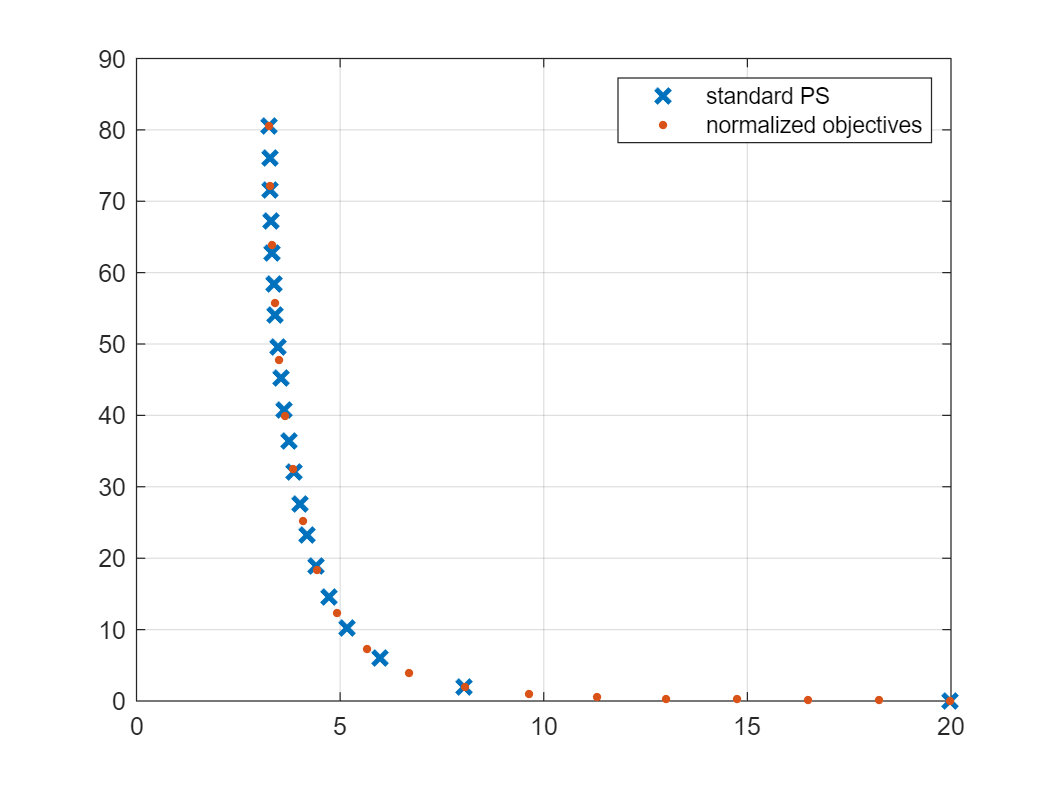

plot(J(:,1), J(:,2), 'x', 'MarkerSize', 8, 'LineWidth', 2)
hold on
plot(Jnorm(:,1), Jnorm(:,2), '.', 'MarkerSize', 10)
legend("standard PS", "normalized objectives")
grid on

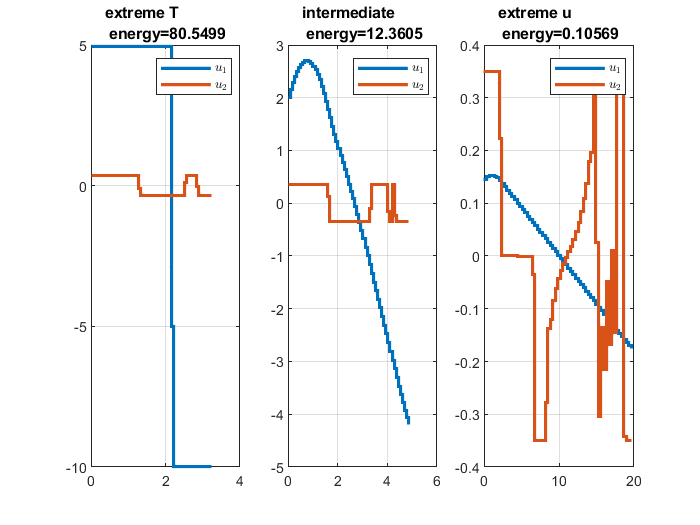

figure
subplot(1,3,1)
stairs(0:sol_norm(1).value(dt):sol_norm(1).value(T-dt), sol_norm(1).value(u)', 'LineWidth', 2)
legend({'$u_1$', '$u_2$'}, 'Interpreter', 'latex')
title("extreme T \newline energy=" + sol_norm(1).value(cost_u))
grid on

subplot(1,3,2)
stairs(0:(sol_norm(round(nParetoPoints/2)).value(dt)):sol_norm(round(nParetoPoints/2)).value(T-dt), sol_norm(round(nParetoPoints/2)).value(u)', 'LineWidth', 2)
legend({'$u_1$', '$u_2$'}, 'Interpreter', 'latex')
title("intermediate \newline energy=" + sol_norm(round(nParetoPoints/2)).value(cost_u))
grid on

subplot(1,3,3)
stairs(0:(sol_norm(end).value(dt)):sol_norm(end).value(T-dt), sol_norm(end).value(u)', 'LineWidth', 2)
legend({'$u_1$', '$u_2$'}, 'Interpreter', 'latex')
title("extreme u \newline energy=" + sol_norm(end).value(cost_u))
grid on

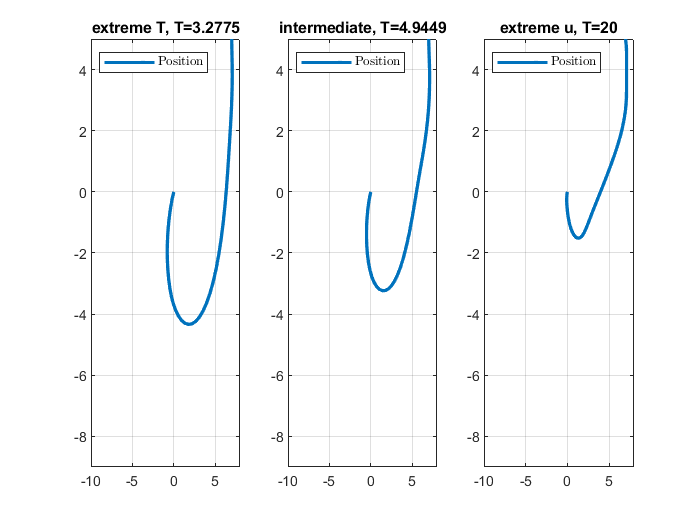


figure;
subplot(1,3,1)
plot(sol_norm(1).value(x(1,:)), sol_norm(1).value(x(2,:)), 'LineWidth', 2)
legend({'Position'}, 'Interpreter', 'latex', 'Location', 'northwest')
title("extreme T, T=" + sol_norm(1).value(T))
xlim([-10 8])
ylim([-9 5])
grid on

subplot(1,3,2)
plot(sol_norm(round(nParetoPoints/2)).value(x(1,:)), sol_norm(round(nParetoPoints/2)).value(x(2,:)), 'LineWidth', 2)
legend({'Position'}, 'Interpreter', 'latex', 'Location', 'northwest')
title("intermediate, T=" + sol_norm(round(nParetoPoints/2)).value(T))
xlim([-10 8])
ylim([-9 5])
grid on

subplot(1,3,3)
plot(sol_norm(end).value(x(1,:)), sol_norm(end).value(x(2,:)), 'LineWidth', 2)
legend({'Position'}, 'Interpreter', 'latex', 'Location', 'northwest')
title("extreme u, T=" + sol_norm(end).value(T))
xlim([-10 8])
ylim([-9 5])
grid on

## Runge-Kutta 4 integrator

function x_end = ms_step(x0, u_series, dt)
% calculate one multiple shooting step with step size dt
import casadi.*

x0_rk = x0;
k = casadi.MX( size( x0, 1 ), 4 );

for i = 1:size( u_series, 2 )
    k(:,1) = robot_ode(x0_rk(:,end), u_series(:,i));
    k(:,2) = robot_ode(x0_rk(:,end) + dt / 2 * k(:,1), u_series(:,i));
    k(:,3) = robot_ode(x0_rk(:,end) + dt / 2 * k(:,2), u_series(:,i));
    k(:,4) = robot_ode(x0_rk(:,end) + dt * k(:,3), u_series(:,i));
    x0_rk  = [x0_rk, x0_rk(:,end) + dt / 6 * k * [1 2 2 1]'];
end

x_end = x0_rk(:, end);
end

## Robot ODE

function xdot = robot_ode(x, u)
    l = 1;
    xdot = [x(3)*cos( x(4) + x(5) ); x(3)*sin( x(4) + x(5) ); u(1); x(3) / l * sin( x(5) ); u(2)];
end
function s_pts = get_starting_points(EP, nParetoPoints)
    weights = (linspace(0,1,nParetoPoints));
    weights = ([1-weights; weights]);
    s_pts = weights'*EP;
end